# Lesson 5

Written by Brenda So and Cory Nezin

# Objective

After this class, you should be able to:

- Understand datatypes in MATLAB

- Understand character arrays and strings in MATLAB

- Understand the Object Oriented Programming in MATLAB

- Know how to input and output file in MATLAB

Before now we have been exploring numeric functions in MATLAB 

# Data Types

There are several basic data types in MATLAB:

- single, double

- int8, int16, int32, int64

- uint8, uint16, uint32, uint64

- logical

- string, char

- cell arrays

You can get the data type of a variable using the class function.

 a = 10;
 class(a)

ans = double

 b = int8(a);
 class(b)

ans = int8

##  Data Type Sizes

Different data types take up different amounts of space in your memory and hard drive.  Let's take a look at some standard sizes in MATLAB.

 clear
 A = randn(1,'double');
 B = randn(1,'single');
 C = true(1);
 D = 'D'

D = D

 whos

  Name      Size            Bytes  Class      Attributes

  A         1x1                 8  double               
  B         1x1                 4  single               
  C         1x1                 1  logical              
  D         1x1                 2  char                 



If your data is getting to large, it can help to cast as a single.  Logicals take up a whole byte.  Surprising?

## Different Interpretations

Be careful with what data types you feed into built in functions.  MATLAB will have different responses to different types

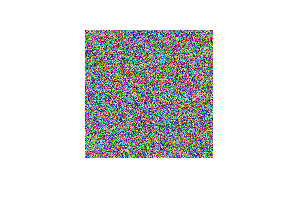

 imshow(uint8(255*rand(128,128,3)))

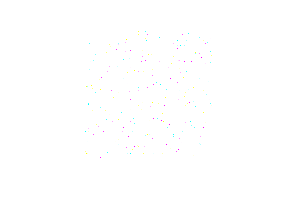

 imshow(double(255*rand(128,128,3)))

## Overflow and Underflow

With floating point, we are trying to represent real numbers.  Obviously there must be some spacing between representable numbers, let's take a look.

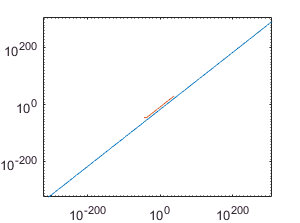

L = logspace(-308,308,4096);
loglog(L,eps(L),single(L),eps(single(L)))

As the plot proves, doubles have a much larger extent as well as more precision at each point.  Let's see how this applies in practice.


eps(1)

ans =      2.220446049250313e-16


(1 + 0.5001*eps(1)) - 1

ans =      2.220446049250313e-16


(1 + 0.4999*eps(1)) - 1

ans =      0


1 + 1e16 == 1e16

ans =    1


    
single(10^50)

ans =    Inf


single(10^-50)

ans =      0


uint8(256)

ans =    255


int8(-129)

ans =    -128


## Cell Arrays

Cell arrays are useful when you have data that is not well structured.  However, it is also relatively slow and hard to deal with compared to matrices.  You should use them sparingly.

courses = {'' 'Modern Physics', 'Signals and Systems', 'Complex Analysis', 'Drawing and Sketching for Engineers';...
           'Grades', 70 + 3*randn(132,1), 80 + 3*randn(41,1), 40 + 3*randn(20,1), 100*ones(29,1);...
           'Teachers', {'Debroy';'Yecko'},{'Fontaine'},{'Smyth'},{'Dell'}}

courses =     ''            'Modern Physics'    'Signals and Systems'    'Complex Analysis'    'Drawing and Sketching for Engineers'
    'Grades'      [132×1 double]    [41×1 double]    [20×1 double]    [29×1 double]
    'Teachers'    {  2×1 cell  }    { 1×1 cell  }    { 1×1 cell  }    { 1×1 cell  }


           
courses(1,2)

ans =     'Modern Physics'


courses{1,2}

ans = Modern Physics

courses{2,2}(3:5,1)

ans =   65.516507672683204
  74.656418135757235
  69.813391873459253


courses(3,2)

ans =     {2×1 cell}


courses{3,2}

ans =     'Debroy'
    'Yecko'


courses{3,2}{1}(1)

ans = D

# Character Arrays and Strings

## Character Arrays

clear
myString = 'Hello World!';
whos

  Name          Size            Bytes  Class    Attributes

  myString      1x12               24  char               



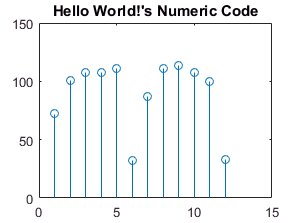

stem(uint16(myString))
title([myString '''s' ' Numeric Code'])

## sprintf

The sprintf function is useful in formatting strings to be output.

numberOfStudents = 20;
section = 'B';
averageGrade = mean(40 + randn(numberOfStudents,1));
sprintf('There are %d students in physics section %s with an average grade of %0.2f',...
        numberOfStudents,section,averageGrade)

ans = There are 20 students in physics section B with an average grade of 40.18

numberOfStudents = 41;
averageGrade = mean([-inf; 80 + randn(numberOfStudents,1)]);
sprintf('There are %04d students in signals with an average grade of...\n %0.2f',...
        numberOfStudents,averageGrade)

ans = There are 0041 students in signals with an average grade of...
 -Inf

plotTitles = ['Hello World!';...
              'This will never ';...
              'work!'];

Dimensions of matrices being concatenated are not consistent.

## String Arrays 

String arrays are a new feature of MATLAB (only implemented in the last year).

plotLegends = [string('Hello World!');...
string('This will indeed ');...
string('work')]

plotLegends =     "Hello World!"
    "This will indeed "
    "work"


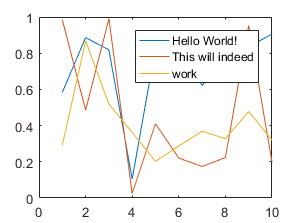

plot(rand(10,3))
legend(plotLegends)

plotLegends(3)

ans = work

plotLegends{3}(4)

ans = k

## Parsing

using strsplit, you can separate strings based on certain qualifications, most commonly whitespace.  This function is also compatible with regex.

s = ['The rain in Spain stays' newline 'mainly in the plain.';]

s = The rain in Spain stays
mainly in the plain.

sprintf(s)

ans = The rain in Spain stays
mainly in the plain.

strsplit(s)

ans =     'The'    'rain'    'in'    'Spain'    'stays'    'mainly'    'in'    'the'    'plain.'


strsplit(s,'n')

ans =     'The rai'    ' i'    ' Spai'    ' stays…'    'ly i'    ' the plai'    '.'


[cellArray, delimiters] = strsplit(s,{'n' 'h'})

cellArray =     'T'    'e rai'    ' i'    ' Spai'    ' stays…'    'ly i'    ' t'    'e plai'    '.'


delimiters =     'h'    'n'    'n'    'n'    'n'    'n'    'h'    'n'


All of this can also be done using the new function split.  The primary difference is that split will instead return a string array instead of a cell array.

split(s)

ans =     "The"
    "rain"
    "in"
    "Spain"
    "stays"
    "mainly"
    "in"
    "the"
    "plain."


## Finding Substrings

In a similar fashion, you can search for patterns in strings using strfind.

s

s = The rain in Spain stays
mainly in the plain.

idx = strfind(s,'in')

idx =      7    10    16    27    32    42


vec = @(v) v(:);
s(vec([idx ; idx + 1]))

ans = inininininin

# Objects and Classes

MATLAB is an OOP language, the variety of toolboxes that MATLAB has (machine learning, filter, even fixed point numbers) are enclosed in classes. You might not need to write your own classes in your years of Cooper, but understanding how classes work in MATLAB would allow you to use those toolboxes effectively and efficiently. 

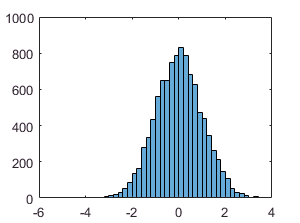

x = randn(10000,1);
h = histogram(x);

properties(h)


Properties for class matlab.graphics.chart.primitive.Histogram:

    Data
    BinCounts
    BinCountsMode
    NumBins
    BinEdges
    BinWidth
    BinMethod
    BinLimits
    BinLimitsMode
    Normalization
    FaceColor
    EdgeColor
    LineWidth
    LineStyle
    DisplayStyle
    Orientation
    FaceAlpha
    EdgeAlpha
    Values
    Children
    Parent
    Visible
    HandleVisibility
    DisplayName
    Annotation
    Selected
    SelectionHighlight
    HitTest
    PickableParts
    UIContextMenu
    ButtonDownFcn
    BusyAction
    BeingDeleted
    Interruptible
    CreateFcn
    DeleteFcn
    Type
    Tag
    UserData



methods(h)


Methods for class matlab.graphics.chart.primitive.Histogram:

Histogram    cat          eq           get          java         reset        
addlistener  clo          fewerbins    horzcat      morebins     set          
addprop      double       findobj      isprop       ne           vertcat      

Static methods:

loadobj      

Methods of matlab.graphics.chart.primitive.Histogram inherited from handle.



To write your own classes, you can use the syntax in BasicClass.m . 

## Structs vs Objects

Another thing you can write in MATLAB are your own structs. Structs are mini versions of objects. The main  difference is that objects have classes but structs do not. To make your own structs, you can do the following

field1 = 'f1';  value1 = zeros(1,10);
field2 = 'f2';  value2 = {'a', 'b'};
field3 = 'f3';  value3 = {pi, pi.^2};
field4 = 'f4';  value4 = {'fourth'};
s = struct(field1,value1,field2,value2,field3,value3,field4,value4)

s =   1×2 struct array with fields:

    f1
    f2
    f3
    f4


s(1)

ans =     f1: [0 0 0 0 0 0 0 0 0 0]
    f2: 'a'
    f3: 3.141592653589793
    f4: 'fourth'


s(2)

ans =     f1: [0 0 0 0 0 0 0 0 0 0]
    f2: 'b'
    f3: 9.869604401089358
    f4: 'fourth'


# File I/O

Very often, you would need to process files that are not already in MATLAB. For instance, if you have a commo separated value file (csv), you would need to find a systematic way to load all your data into MATLAB. Moreover, you might also want to export figures and data from MATLAB, hence the need to learn file IO. I am only convering a subset of file IO in this MATLAB, more information can be found here : [https://www.mathworks.com/help/matlab/import_export/supported-file-formats.html](https://www.mathworks.com/help/matlab/import_export/supported-file-formats.html) . 

## Importing data

mypic = load('mypic.mat');                % Import a .mat file
[y, Fs] = audioread('hallelujah.wav');    % Import an audio
fileID = fopen('grades.txt');
C_text = textscan(fileID,'%s',4,'Delimiter','|')    % Import a textfile

C_text =     {4×1 cell}


C_data0 = textscan(fileID,'%d %f %f %f')            % Import the data in the textfile  

C_data0 =     [4×1 int32]    [4×1 double]    [4×1 double]    [4×1 double]


Error using celldisp (line 14)
Must be a cell array.

C_data0{1}

Note that when importing a textfile, it returns an array of cells to you. 

## Exporting data

save('allData')                  % saves your whole workspace into a .mat file
audiowrite('mySong.wav',y,Fs)    % saves audio
fileID = fopen('myFile.txt','w');
fprintf(fileID,'1 Januar 2014, 20.2, 100.5 \n');
fprintf(fileID,'1 Februar 2014, 21.6, 102.7 \n');
fprintf(fileID,'1 März 2014, 20.7, 99.8 \n');
fclose(fileID);